%4 focus imaging system
Nx=1024;
Ny=1024;
dx=10e-6;
dy=10e-6;
xmax = Nx*dx;
ymax=Ny*dy;
lam=0.532e-6;
lensD = 6e-3;

x=-xmax/2:dx:xmax/2-dx;
y=-ymax/2:dy:ymax/2-dy;
[X, Y] = meshgrid(x, y);

%M = floor(fxMax / dfx); % Ensuring integer value for grid consistency 
%fyMax = 1 / (dy); % Maximum frequency (from sampling theorem)
%dfy = 1/(Ny*dy)
% fo = 0;
% zoom(0.1*)/shift Frequency grid
% 
%intermediate calc not important
% w(f)^2 = wz = wo^2*(1+(f^2*lam^2)/(pi^2*wo^4));
% 
% focal length
% f = zR*(wf/wo)*sqrt(1-wo^2/wf^2);
% 
% Set Size of beam at focal spot w(f) equal to radius of lens
%Set wo to be characteristic radius of focused wave (i guess dx)
wf = lensD/2;
wo=dx

wo = 1.0000e-05

%Minimum focal length
% 
win = xmax/10;
zR = (pi*dx^2)/lam; %  Rayleigh Range
%
%fmin = 2*zR*(rLens/dx)*sqrt(1-(dx^2/(4*rLens^2)))
fmin = 2*zR*(wf/dx)*sqrt(1-dx^2/(4*wf^2))

fmin = 0.3543

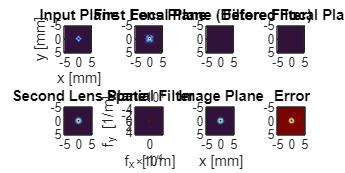

% 
f1 = fmin; f2 = fmin;
% inG = exp(-x^2/w^2)*1/2*(1+cos(2*pi*f*x)); cosine grate fmod=6/win in x
% and y
fmod=6/win;
inG = exp((-(X.^2+Y.^2))/(win^2));
mod = (1+cos(2*pi*fmod*X).*cos(2*pi*fmod*Y))/2;
inG2 = inG.*mod;
%%
ko = ((2*pi)/lam);
R = sqrt(X.^2 + Y.^2);
tmission = double(R<=lensD/2) .* exp(-1i*ko/(2*fmin)*R.^2); %oParaxial Limit R=3mm
% imagesc(x, y, out)
% axis image

% Construct and apply a unit amplitude, (top-hat) circular spatial filter with a cutoff frequency large enough to pass the DC peak but
% small enough to filter out the modulation
% Propagation function (same as before)
function Uout = propagate(Uin, d, lam, dx, dy)
    [Nx, Ny] = size(Uin);
    dfx = 1 / (Nx * dx);
    dfy = 1 / (Ny * dy);
    fxMax = 1/(2*dx); %-fxMax/2:dfx:fxMax/2-dfx; 
    fyMax = 1/(2*dy); %-fyMax/2:dfy:fyMax/2-dfy;
    fx = (-Nx/2:Nx/2-1)/(Nx*dx);
    fy = (-Ny/2:Ny/2-1)/(Ny*dx);
    [FX, FY] = meshgrid(fx, fy); %exp(1i * k * d) .*
    H =  exp(-1i * pi * lam * d * (FX.^2 + FY.^2));
    Uout = ifft2(ifftshift(fftshift(fft2(Uin)) .* H));
end

% Simulate 4-f system and capture all planes
% 1. Input Plane
field_input = inG2;

% 2. Propagate to Lens Plane 1
field_input = propagate(field_input, f1, lam, dx, dy);

% 3. Apply Lens 1 (First Lens Plane)
field_input = field_input .* tmission;

% 4. Propagate to Focal Plane
field_focal = propagate(field_input, f1, lam, dx, dy);

% 5. Spatial Filter (Focal Plane Filtering)
dfx = 1 / (Nx * dx);
dfy = 1 / (Ny * dy);
fx = (-Nx/2:Nx/2-1) * dfx;
fy = (-Ny/2:Ny/2-1) * dfy;
[FX, FY] = meshgrid(fx, fy);
f_cutoff = 0.8 * fmod;
spatial_filter = circ(double(sqrt(FX.^2 + FY.^2)), f_cutoff);  % Your circ function
field_filtered_focal = field_focal .* spatial_filter;

% 6. Propagate to Lens Plane 2
field_lens2_before = propagate(field_filtered_focal, f2, lam, dx, dy);

% 7. Apply Lens 2 (Second Lens Plane)
field_lens2_after = field_lens2_before .* tmission;

% 8. Propagate to Image Plane
output_beam = propagate(field_lens2_after, f2, lam, dx, dy);

% Error calculation
original_beam = exp(-(X.^2 + Y.^2)/(win^2));
error = abs(output_beam).^2 - abs(original_beam).^2;
% 1) The input wave (the field sampled along the input plane) is propagated through free space a distance Subscript[f, 1] to lens plane 1
% 2) The transmission function of lens 1 is applied to the field at lens plane 1
% 3) The field is propagated through free space a distance Subscript[f, 1] to the focal plane of lens 1 (focal plane)
% 4) A spatial filter is applied at the focal plane
% 5) The field after the spatial filter is propagated through free space a distance Subscript[f, 2] to the second lens (lens plane 2)
% 6) The transmission function of lens 2 is applied to the field at lens plane 2
% 7) The field after lens 2 is propagated through free space a distance Subscript[f, 2] to the output plane
%

%field at lens plane distance d away
%exp(1i*ko*d)*inversefft(fft(input wave)*exp(-1i*pi*lam*d*(fx^2_fy^2)))
%previous step multiply by spherical transmission func
%use single fresnel FT version on last step to propogate to focus plane of
%lens 1
%apply spatial filter 
%repeat field at lens plane distance away
%repeat apply spherical transmission func
%repeat single fresnel ft version to get to output plane

% Plot all 8 planes
figure('Position', [100, 100, 1200, 600]);

% 1. Input Plane
subplot(2,4,1);
imagesc(x*1e3, x*1e3, abs(inG2).^2);
axis image; title('Input Plane'); xlabel('x [mm]'); ylabel('y [mm]');

% 2. First Lens Plane (after lens)
subplot(2,4,2);
imagesc(x*1e3, x*1e3, abs(field_input).^2);
axis image; title('First Lens Plane');

% 3. Focal Plane (before filtering)
subplot(2,4,3);
imagesc(x*1e3, x*1e3, abs(field_focal).^2);
axis image; title('Focal Plane (Before Filter)');

% 4. Filtered Focal Plane
subplot(2,4,4);
imagesc(x*1e3, x*1e3, abs(field_filtered_focal).^2);
axis image; title('Filtered Focal Plane');

% 5. Second Lens Plane (after lens)
subplot(2,4,5);
imagesc(x*1e3, x*1e3, abs(field_lens2_after).^2);
axis image; title('Second Lens Plane');

% 6. Spatial Filter Mask
subplot(2,4,6);
imagesc(fx, fx, spatial_filter);
axis image; title('Spatial Filter'); 
xlabel('f_x [1/m]'); ylabel('f_y [1/m]');

% 7. Image Plane
subplot(2,4,7);
imagesc(x*1e3, x*1e3, abs(output_beam).^2);
axis image; title('Image Plane'); xlabel('x [mm]');

% 8. Error
subplot(2,4,8);
imagesc(x*1e3, x*1e3, error);
axis image; title('Error');
colormap("turbo")


% Board math
% fT = exp(-fx^2*w^2)+1/2*exp^(-(fx-fo)^2*w^2/4)+exp^(-(fx+fo)^2*w^2/4)

%%fmin/4
%dx/2 fmin is output diameter >=1 pixel size

% Super-Gaussian filter
superGauss = exp(-(sqrt(FX.^2 + FY.^2) / f_cutoff).^4);

% Apply super-Gaussian filter
fieldFilterFocusSuperGauss = field_focal .* superGauss;

% Propagate to Lens Plane 2 with super-Gaussian filter
lens2_before_SuperGauss = propagate(fieldFilterFocusSuperGauss, f2, lam, dx, dy);

% Apply Lens 2
lens2_after_SuperGauss = lens2_before_SuperGauss .* tmission;

% Propagate to Image Plane with super-Gaussian filter
outBeam_SuperGauss = propagate(lens2_after_SuperGauss, f2, lam, dx, dy);

% Error calculation for super-Gaussian filter
error_superGaussian = abs(outBeam_SuperGauss).^2 - abs(original_beam).^2;

% Compare errors
fprintf('Top-hat filter error: %.4f\n', sum(abs(error(:))));

Top-hat filter error: 12353.2466


fprintf('Super-Gaussian filter error: %.4f\n', sum(abs(error_superGaussian(:))));

Super-Gaussian filter error: 12354.1593


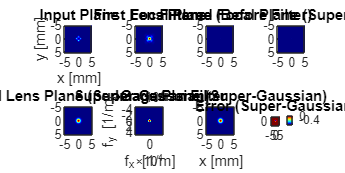

% Plot super-Gaussian filter results
figure('Position', [100, 100, 1200, 600]);

% 1. Input Plane
subplot(2,4,1);
imagesc(x*1e3, x*1e3, abs(inG2).^2);
axis image; title('Input Plane'); xlabel('x [mm]'); ylabel('y [mm]');

% 2. First Lens Plane (after lens)
subplot(2,4,2);
imagesc(x*1e3, x*1e3, abs(field_input).^2);
axis image; title('First Lens Plane');

% 3. Focal Plane (before filtering)
subplot(2,4,3);
imagesc(x*1e3, x*1e3, abs(field_focal).^2);
axis image; title('Focal Plane (Before Filter)');

% 4. Filtered Focal Plane (Super-Gaussian)
subplot(2,4,4);
imagesc(x*1e3, x*1e3, abs(fieldFilterFocusSuperGauss).^2);
axis image; title('Filtered Focal Plane (Super-Gaussian)');

% 5. Second Lens Plane (Super-Gaussian)
subplot(2,4,5);
imagesc(x*1e3, x*1e3, abs(lens2_after_SuperGauss).^2);
axis image; title('Second Lens Plane (Super-Gaussian)');

% 6. Spatial Filter Mask (Super-Gaussian)
subplot(2,4,6);
imagesc(fx, fx, superGauss);
axis image; title('Super-Gaussian Filter'); 
xlabel('f_x [1/m]'); ylabel('f_y [1/m]');

% 7. Image Plane (Super-Gaussian)
subplot(2,4,7);
imagesc(x*1e3, x*1e3, abs(outBeam_SuperGauss).^2);
axis image; title('Image Plane (Super-Gaussian)'); xlabel('x [mm]');

% 8. Error (Super-Gaussian)
subplot(2,4,8);
imagesc(x*1e3, x*1e3, error_superGaussian);
axis image; title('Error (Super-Gaussian)'); colormap jet;
colorbar;

% Lower modulation frequency to 20%
fmodLow = 0.2 * fmod;

% Update input beam with lower modulation frequency
modLow = (1 + cos(2*pi*fmodLow*X).*cos(2*pi*fmodLow*Y)) / 2;
inG2Low = inG .* modLow;

% Repeat the simulation with the lower modulation frequency
fieldInLow = inG2Low;
fieldInLow = propagate(fieldInLow, f1, lam, dx, dy);
fieldInLow = fieldInLow .* tmission;
fieldFocalLow = propagate(fieldInLow, f1, lam, dx, dy);

% Top-hat filter
spatialFilterLow = circ(double(sqrt(FX.^2 + FY.^2)), 0.8 * fmod_low);
fieldFilterFocalLow = field_focal_low .* spatialFilterLow;
lens2BeforeLow = propagate(fieldFilterFocalLow, f2, lam, dx, dy);
lens2AfterLow = lens2BeforeLow .* tmission;
outBeamLow = propagate(lens2AfterLow, f2, lam, dx, dy);
error_low = abs(outBeamLow).^2 - abs(original_beam).^2;

% Super-Gaussian filter
superGaussFilterLow = exp(-(sqrt(FX.^2 + FY.^2) / (0.8 * fmod_low)).^4);
fieldFilterFocalsuperGaussLow = field_focal_low .* superGaussFilterLow;
lens2_before_superGaussLow = propagate(fieldFilterFocalsuperGaussLow, f2, lam, dx, dy);
lens2_after_superGaussLow = lens2_before_superGaussLow .* tmission;
outbeam_superGaussLow = propagate(lens2_after_superGaussLow, f2, lam, dx, dy);
error_superGaussLow = abs(outbeam_superGaussLow).^2 - abs(original_beam).^2;

% Compare errors
fprintf('Top-hat filter error (low modulation): %.4f\n', sum(abs(error_low(:))));

Top-hat filter error (low modulation): 12379.2858


fprintf('Super-Gaussian filter error (low modulation): %.4f\n', sum(abs(error_superGaussLow(:))));

Super-Gaussian filter error (low modulation): 12776.1986


%Import the Siemens Star for Filtering
lensD2 = 12e-3

lensD2 = 0.0120

wf2 = lensD2/2;
fmin2 = 2*zR*(wf2/dx)*sqrt(1-dx^2/(4*wf2^2))

fmin2 = 0.7086

% 
f1s = fmin2; f2s = fmin2;
tmission2 = double(R<=wf2) .* exp(-1i*ko/(2*fmin)*R.^2); %oParaxial Limit R=3mm
sStar = imread('C:\Program Files\MATLAB\R2024a\toolbox\images\imdata\testpat1.png')

sStar = 256×256 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   196   163   255   254   147   226   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   125    61   255   240    28   185   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   129    67   255  

dub = double(sStar)

dub =    255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   196   163   255   254   147   226   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   125    61   255   240    28   185   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   129    67   255   241    35   188   255 

reSize = imresize(dub, [Nx, Ny])

reSize =   255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  254.9527  254.6962  254.4936  254.6692  255.5542  257.2203  259.2406  261.1483  262.6434  264.2311  265.5378  266.0196  265.0600  262.3322  258.8885  255.9263  254.4082  253.6998  253.6845  254.4336  256.2392  259.8674  264.0047  267.0470
  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  254.9779  254.8582  254.7637  254.8456  255.2586  256.0361  256.9790  257.8692  258.5669  259.3079  259.9177  260.1425  259.6947  258.4217  256.8146  255.4323  254.7238  254.3933  254.3861  254.7357  255.5783  257.2715  259.2022

%DeepSeek Use of crop to keep image same size
rotated = imrotate(reSize, -20, "crop") 

rotated =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

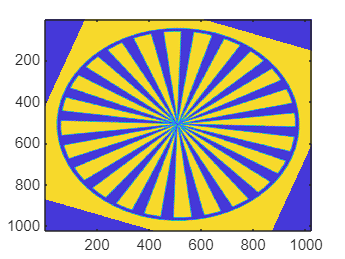

close all;
imagesc(rotated)

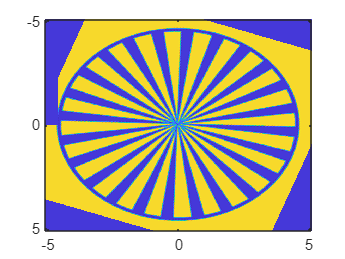

rotated(1:Nx/2,1:50)=0;
rotated = rotated/max(rotated(:));
imagesc(x*1e3, y*1e3, rotated)

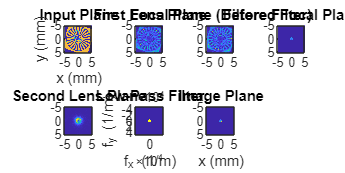

SStar = rotated;

% 2. Propagate to Lens Plane 1
SStar = propagate(SStar, f1, lam, dx, dy);

% 3. Apply Lens 1 (First Lens Plane)
SStar = SStar .* tmission2;

% 4. Propagate to Focal Plane
focalSStar = propagate(SStar, f1s, lam, dx, dy);

% 5. Apply Low-Pass Filter (Disc)
fx = (-Nx/2:Nx/2-1)/(Nx*dx);
[FX, FY] = meshgrid(fx, fx);
f_cutoff = 0.1 * max(fx); % Adjust cutoff frequency
low_pass_filter = double(sqrt(FX.^2 + FY.^2) <= f_cutoff);
high_pass_filter = 1-double(sqrt(FX.^2 + FY.^2) <= f_cutoff);
phase_contrast = exp(1i * pi/2) .* low_pass_filter + 1 .* (high_pass_filter);

% Apply Low-Pass Filter
lowPassSStar = focalSStar .* low_pass_filter;
highPassSStar = focalSStar .* high_pass_filter;
phaseSStar = focalSStar .* phase_contrast;


% 6. Propagate to Lens Plane 2
sStar_lens2_Before = propagate(lowPassSStar, f2s, lam, dx, dy);
sStar_lens2_BeforeH = propagate(highPassSStar, f2s, lam, dx, dy);
sStar_lens2_BeforePh = propagate(phaseSStar, f2s, lam, dx, dy);

% 7. Apply Lens 2 (Second Lens Plane)
sStar_lens2_After = sStar_lens2_Before .* tmission2;
sStar_lens2_AfterH = sStar_lens2_BeforeH .* tmission2;
sStar_lens2_AfterPh = sStar_lens2_BeforePh .* tmission2;

% 8. Propagate to Image Plane
outputBeamSS = propagate(sStar_lens2_After, f2s, lam, dx, dy);
outputBeamSSH = propagate(sStar_lens2_AfterH, f2s, lam, dx, dy);
outputBeamSSPH = propagate(sStar_lens2_AfterPh, f2s, lam, dx, dy);

% Display results
figure('Position', [100, 100, 1200, 600]);

% 1. Input Plane
subplot(2,4,1);
imagesc(x*1e3, y*1e3, abs(rotated).^2);
axis image; title('Input Plane'); xlabel('x (mm)'); ylabel('y (mm)');

% 2. First Lens Plane
subplot(2,4,2);
imagesc(x*1e3, y*1e3, abs(SStar).^2);
axis image; title('First Lens Plane');

% 3. Focal Plane (Before Filtering)
subplot(2,4,3);
imagesc(x*1e3, y*1e3, abs(focalSStar).^2);
axis image; title('Focal Plane (Before Filter)');

% 4. Filtered Focal Plane
subplot(2,4,4);
imagesc(x*1e3, y*1e3, abs(lowPassSStar).^2);
axis image; title('Filtered Focal Plane');

% 5. Second Lens Plane
subplot(2,4,5);
imagesc(x*1e3, y*1e3, abs(sStar_lens2_After).^2);
axis image; title('Second Lens Plane');

% 6. Spatial Filter Mask
subplot(2,4,6);
imagesc(fx, fx, low_pass_filter);
axis image; title('Low-Pass Filter'); 
xlabel('f_x (1/m)'); ylabel('f_y (1/m)');

% 7. Image Plane
subplot(2,4,7);
imagesc(x*1e3, y*1e3, abs(outputBeamSS).^2);
axis image; title('Image Plane'); xlabel('x (mm)');

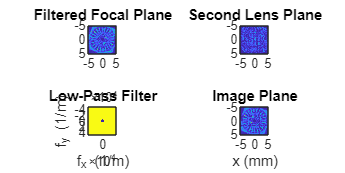


% 8. Error Was not working
% error = abs(outputBeamSS).^2 - abs(sStar).^2;
% subplot(2,4,8);
% imagesc(x*1e3, y*1e3, error);
% axis image; title('Error'); colormap gray;
% colorbar;

% Display results
figure('Position', [100, 100, 1200, 600]);

% 4. High Filtered Focal Plane
subplot(2,2,1);
imagesc(x*1e3, y*1e3, abs(highPassSStar).^2);
axis image; title('Filtered Focal Plane');

% 5. High Second Lens Plane
subplot(2,2,2);
imagesc(x*1e3, y*1e3, abs(sStar_lens2_AfterH).^2);
axis image; title('Second Lens Plane');

% 6. High Spatial Filter Mask
subplot(2,2,3);
imagesc(fx, fx, high_pass_filter);
axis image; title('Low-Pass Filter'); 
xlabel('f_x (1/m)'); ylabel('f_y (1/m)');

% 7. High Image Plane
subplot(2,2,4);
imagesc(x*1e3, y*1e3, abs(outputBeamSSH).^2);
axis image; title('Image Plane'); xlabel('x (mm)');

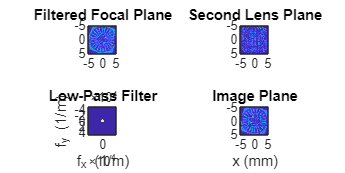


% Display results
figure('Position', [100, 100, 1200, 600]);
%Did Not Have Time to Do the Band Pass Filter
%Deep Seek helped implement the phase contrast filter
%though it does not look correct
% 4. Phase Filtered Focal Plane
subplot(2,2,1);
imagesc(x*1e3, y*1e3, abs(phaseSStar).^2);
axis image; title('Filtered Focal Plane');

% 5. Phase Second Lens Plane
subplot(2,2,2);
imagesc(x*1e3, y*1e3, abs(sStar_lens2_AfterPh).^2);
axis image; title('Second Lens Plane');

% 6. Phase Spatial Filter Mask
subplot(2,2,3);
imagesc(fx, fx, angle(phase_contrast));
axis image; title('Low-Pass Filter'); 
xlabel('f_x (1/m)'); ylabel('f_y (1/m)');

% 7. High Image Plane
subplot(2,2,4);
imagesc(x*1e3, y*1e3, abs(outputBeamSSPH).^2);
axis image; title('Image Plane'); xlabel('x (mm)');


%Deep Seek helped me answer these questions about the effects
%of the Siemen Star
% Low-Pass Filter Effects:
% The low-pass filter removes high-frequency components, resulting in a blurred image.
%Fine details near the center of the Siemens star will be lost as the filter cutoff frequency decreases.
%Resolution Determination:
%The Siemens star can be used to determine the resolution of the imaging system by observing the smallest resolvable feature (spoke) near the center.
%The cutoff frequency of the filter directly affects the resolution: a smaller cutoff frequency reduces the system's ability to resolve fine details.
%Quantifying Filter Effects:
%The error map (difference between the filtered and original images) quantifies the loss of detail due to filtering.
%The resolution can be quantified by measuring the smallest resolvable spoke in the Siemens star after filtering.

%2. Purpose in Image Processing:
% Edge Detection:
% 
% High-pass filters are commonly used to detect edges in images, as edges correspond to high-frequency components.
% 
% Sharpening:
% 
% High-pass filters can be used to sharpen images by enhancing high-frequency details.
% 
% Noise Reduction:
% 
% In some cases, high-pass filters can help reduce low-frequency noise while preserving important details